# Statistical Behaviour of Econometric Indicators

Giacomo Marciani

Department of Civil and Computer Engineering

University of Rome Tor Vergata

[gmarciani@acm.org](mailto:gmarciani@acm.org)

## `Abstract`

`This script visualizes a comparative study about the statistical behaviour of important national econometric indicators. The dataset is provided by the World Bank Group[1], through a public REST API[2].`

`The script allows to compare an arbitrary number of econometric indicators, and it is initialized with the following ones:`

- `NY.GDP.MKTP.KD.ZG: Annual percentage growth rate of GDP at market prices based on constant local currency[3].`

- `SL.UEM.TOTL.NE.ZS: Unemployment refers to the share of the labor force that is without work but available for and seeking employment[4].`

`This work is inteded as a final test for the course in Advanced Statistics[5,6,7].`

## `Introduction`

`First of all, let us declare the parameters for the study.`

country = "ITA";
%indicators = ["NY.GDP.MKTP.KD.ZG", "SL.UEM.TOTL.NE.ZS"];
indicators = ["NY.GDP.MKTP.KD.ZG", "SL.UEM.TOTL.NE.ZS", "GC.TAX.YPKG.ZS"];

`You can customize the study by editing the variables ``country`` and ``indicators``. Please, notice that you also have to modify accordingly the variable ``dists`` in Distribution Analysis.`

## `Setup`

`Let us setup the required support variables:`

n = length(indicators);
data = repmat(struct('name', [], 'T', [], 'w', []), n, 1);
for i = 1:n
    data(i).name = indicators(i);
end

## `Annual Trend`

`Let us now visualize the annual trend of the indicators.`

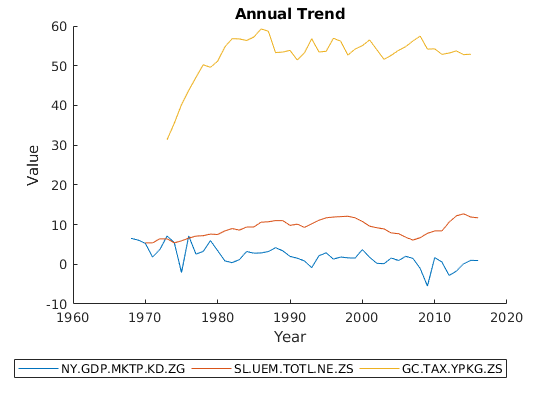

hold on

for i = 1:n
    data(i).T = getWBIndicator(data(i).name, country);
    plot(data(i).T.Date, data(i).T.Value, 'DisplayName', data(i).name);
end

hold off

title('Annual Trend');
xlabel('Year');
ylabel('Value');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');


figure;

## `W-Measure`

`Let us now consider the following measure`


$$w_{i}:=\frac{x_{i}-x_{i-1}}{x_{i-1}}$$


`where `$x_{i}$` is the value of the considered indicator at time `$i$`.`

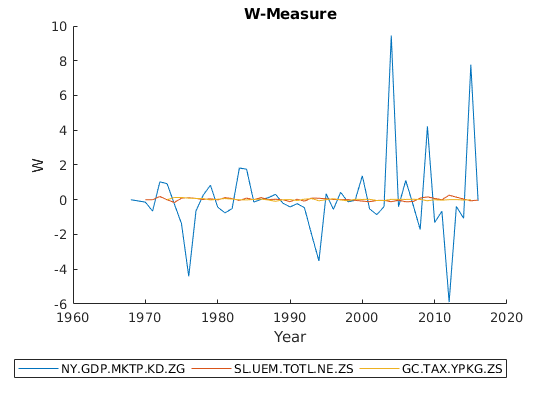

hold on

for i = 1:n
    data(i).w = getW(data(i).T.Value);
    plot(data(i).T.Date, data(i).w, 'DisplayName', data(i).name);
end

hold off

title('W-Measure');
xlabel('Year');
ylabel('W');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');


figure;

## `Distribution Analysis`

`Let us now study the probability distribution function of the W-measure for the indicators. Please, notice that the variable ``dists`` should be modified accordingly to the result reported by the Distribution Fitter.`

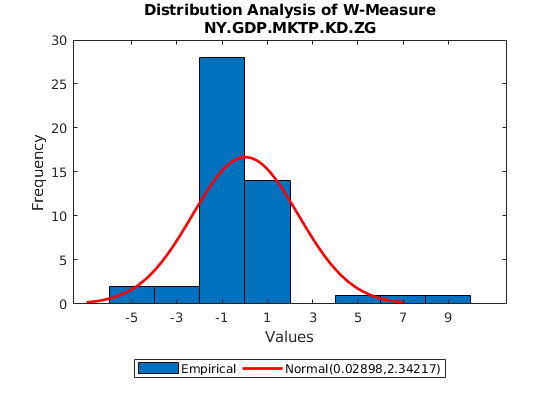

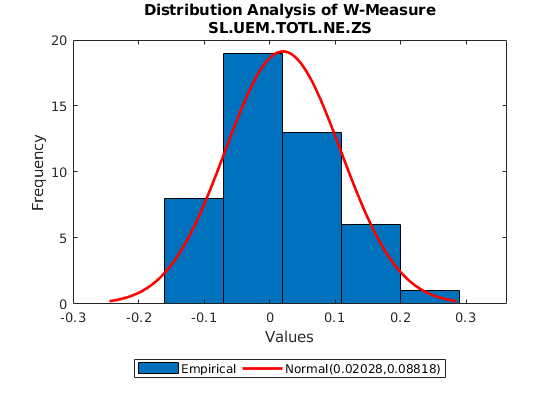

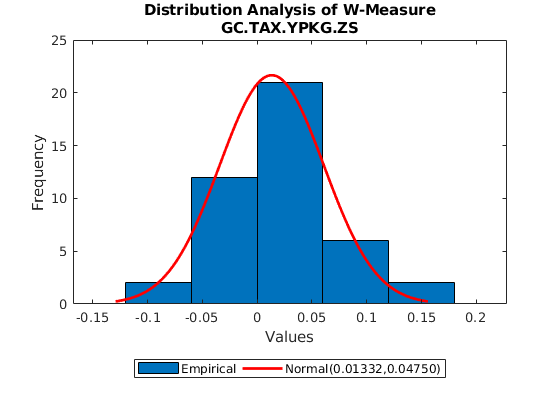

%dists = ["Normal", "Normal"];
dists = ["Normal", "Normal", "Normal"];

for i = 1:n
    bins = size(histcounts(data(i).w), 2);
    dparams = fitdist(data(i).w, char(dists(i)));

    histfit(data(i).w, bins, char(dists(i)));

    title({'Distribution Analysis of W-Measure', data(i).name});
    xlabel('Values');
    ylabel('Frequency');
    legend('Empirical', sprintf("%s(%.5f,%.5f)", dists(i), dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `Correlation Analysis`

`Let us now consider the correlation between the indicators.`

rows = cell(nchoosek(n,2), 3);
ridx = 1;
for i = 1:n
    for j = (i+1):n
        minDate = max(data(i).T.Date(1), data(j).T.Date(1));
        maxDate = min(data(i).T.Date(end), data(j).T.Date(end));
        vlsi = data(i).T(data(i).T.Date >= minDate & data(i).T.Date <= maxDate,:).Value;
        vlsj = data(j).T(data(j).T.Date >= minDate & data(j).T.Date <= maxDate,:).Value;
        corrMatrix = corrcoef(vlsi, vlsj);
        rows(ridx,:) = {data(i).name, data(j).name, corrMatrix(1,2)};
        ridx = ridx + 1;
    end
end
disp(cell2table(rows, 'VariableNames', {'Indicator1','Indicator2','Correlation'}));

        Indicator1             Indicator2         Correlation
    ___________________    ___________________    ___________

    "NY.GDP.MKTP.KD.ZG"    "SL.UEM.TOTL.NE.ZS"    -0.23298   
    "NY.GDP.MKTP.KD.ZG"    "GC.TAX.YPKG.ZS"       -0.39299   
    "SL.UEM.TOTL.NE.ZS"    "GC.TAX.YPKG.ZS"        0.51076   



## `Forecasting`

`Let us now forecast the trend of the indicators by curve fitting. Please, notice that:`

- `fits`` should be modified accordingly to the result reported by the Curve Fitter;.`

- `futureYears`` should be modified accordignly to the desired future projection;`

- `futureSampling`` should be modified accordingly to the desired forecasting sampling;`

- `confidence`` should be modified accordingly to the desired level of confidence.`

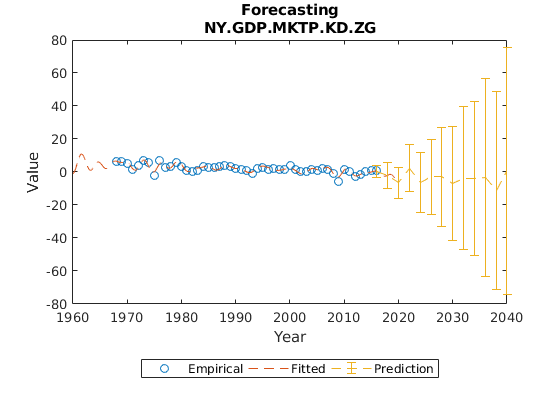

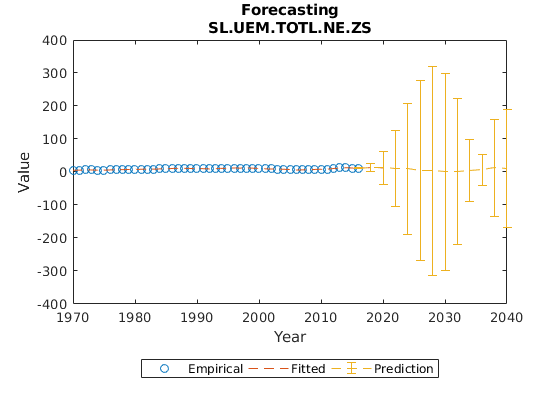

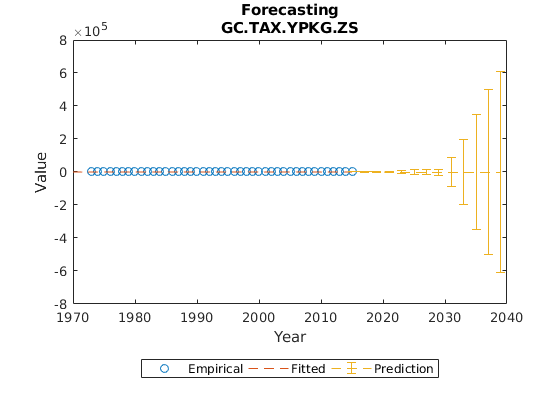

fits = ["sin8", "sin8", "sin8"];
futureYear = 2040;
futureSampling= 2;
confidence = 0.95;

for i = 1:n
    mnYear = min(data(i).T.Date);
    mxYear = max(data(i).T.Date);
    
    fitting = fit(data(i).T.Date, data(i).T.Value, char(fits(i)));
    
    futureInterval = mxYear:futureSampling:futureYear;
    futureValues = fitting(futureInterval);
    ci = predint(fitting, futureInterval, confidence, 'observation');
    
    plot(data(i).T.Date, data(i).T.Value, 'o');
    
    %xlim([mnYear mxYear]);
    hold on
    plot(fitting, '--');
    errorbar(futureInterval, futureValues, futureValues-ci(:,1), ci(:,2)-futureValues, '--');
    hold off
    
    title({'Forecasting', data(i).name});
    xlabel('Year');
    ylabel('Value');
    legend('Empirical', 'Fitted', 'Prediction', 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `KPIs`

`In the end, let us consider the some summarizing KPIs for the indicators.`

rows2 = cell(n, 7);
for i = 1:n
    [Max,Min,YMax,YMin,Mean,Std] = getDescriptors(data(i).T);
    rows2(i,:) = {data(i).name,Max,Min,YMax,YMin,Mean,Std};
end
disp(cell2table(rows2, 'VariableNames', {'Indicator','Max','Min','YMax','YMin','Mean','Std'}));

         Indicator          Max        Min      YMax    YMin     Mean      Std  
    ___________________    ______    _______    ____    ____    ______    ______

    "NY.GDP.MKTP.KD.ZG"    7.1259    -5.4821    1973    2009    2.0067    2.5014
    "SL.UEM.TOTL.NE.ZS"      12.7        5.4    2014    1970    9.0702    2.1454
    "GC.TAX.YPKG.ZS"       59.262     31.345    1986    1973     52.65    5.5871



## `References`

- `The Worl Bank Group, `[`https://www.worldbank.org`](https://www.worldbank.org)

- `The World Bank Open Data, `[`https://data.worldbank.org`](https://data.worldbank.org)

- `The World Bank Group, Definition NY.GDP.MKTP.KD.ZG,`[`https://datacatalog.worldbank.org/search/indicators?query=NY.GDP.MKTP.KD.ZG`](https://datacatalog.worldbank.org/search/indicators?query=NY.GDP.MKTP.KD.ZG)

- `The World Bank Group,  Definition SL.UEM.TOTL.NE.ZS, `[`https://datacatalog.worldbank.org/search/indicators?query=SL.UEM.TOTL.NE.ZS`](https://datacatalog.worldbank.org/search/indicators?query=SL.UEM.TOTL.NE.ZS)

- `Advanced Statistics, `[`http://www.massimoregoli.com/corsi/course/view.php?id=13`](http://www.massimoregoli.com/corsi/course/view.php?id=13)

- `Ross, Sheldon M. ``Introduction to probability and statistics for engineers and scientists``. Academic Press, 2014.`

- `Higham, Desmond J., and Nicholas J. Higham. ``MATLAB guide``. Vol. 150. Siam, 2016.`

## `Functions`

function T = getWBIndicator(indicator,country)
% GETWBINDICATOR Download from WOrldBank and indicator for a country.
% indicator: indicator code (i.e. NY.GDP.MKTP.KD.ZG, SL.UEM.TOTL.NE.ZS)
% country: Country code in ISO3 format (i.e. ITA, DEU)
% T: the data table.
url = sprintf('http://api.worldbank.org/v2/countries/%s/indicators/%s?format=json', country, indicator);
rawData = webread(url);
tblData = struct2table(rawData{2,1});
tblData = tblData(~cellfun(@isempty, tblData.value), :);
dates = cellfun(@str2num, tblData.date);
values = cell2mat(tblData.value);
T = table(dates, values, 'VariableNames', {'Date', 'Value'});
T = sortrows(T, {'Date'});
end

function W = getW(X)
% WMEASURE Compute the W-measure for a vector:
% w(i)=(x(i)-x(i-1))/(x(i-1))
% X: the original vector.
% W: the vector of W-values.
n = size(X, 1);
W = zeros(n, 1);
for i = 2:n
    W(i) = (X(i)-X(i-1))/X(i-1);
end
end

function [Max,Min,YMax,YMin,Mean,Std] = getDescriptors(T)
% GETDESCRIPTORS Compute the notable values of a WB table.
% T: the WB table.
% Max: the maximum value in the series.
% Min: the minimum value in the series.
% YMax: the year of the maximum value of the series.
% YMin: the year of the minimum value of the series.
% Mean: the mean value of the series.
% Std: the standard deviation of the series.
yrs = T.Date;
vls = T.Value;
[Max,iMax] = max(vls);
[Min,iMin] = min(vls);
YMax = yrs(iMax);
YMin = yrs(iMin);
Mean = mean(vls);
Std = std(vls);
end